# Code Cleaning

## Linear Model

### Original Code

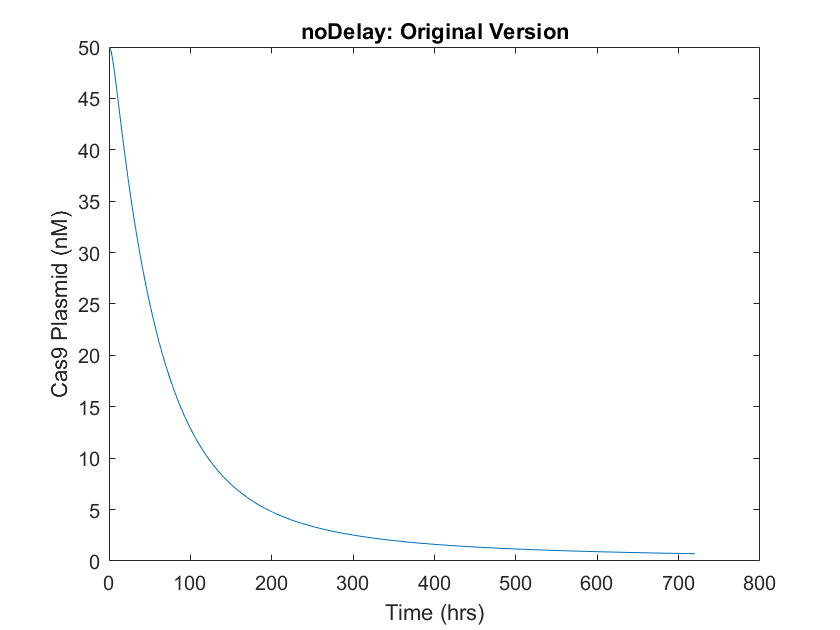

% Read in a table, get all vars
T = readtable('terms-GeneSystemElimination.csv');
fit = 'fit1';
FitTable = T(:,{'varName', [fit, '_fit'], [fit, '_std']});
vars = table2cell(FitTable);
varsToUse = zeros(1, length(vars));
for k = 1:length(vars)
    varsToUse(1, k) = vars{k, 2};
end

% Set tspan
tspan = [0, 720];

% Run model
[tint, yint] = LinearSystemElimination(tspan, varsToUse);

% Plot
plot(tint, yint);
title('noDelay: Original Version')
xlabel('Time (hrs)')
ylabel('Cas9 Plasmid (nM)')

### Clean Version: No idexing of variables

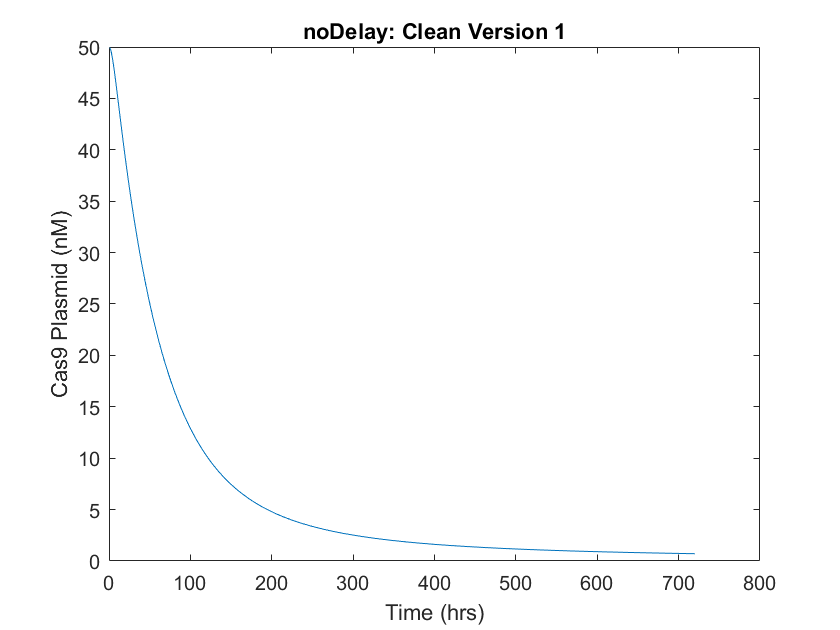

% Run model
[tint, yint] = noDelay(tspan, varsToUse);

% Plot
plot(tint, yint);
title('noDelay: Clean Version 1')
xlabel('Time (hrs)')
ylabel('Cas9 Plasmid (nM)')

## TF

### Original Code

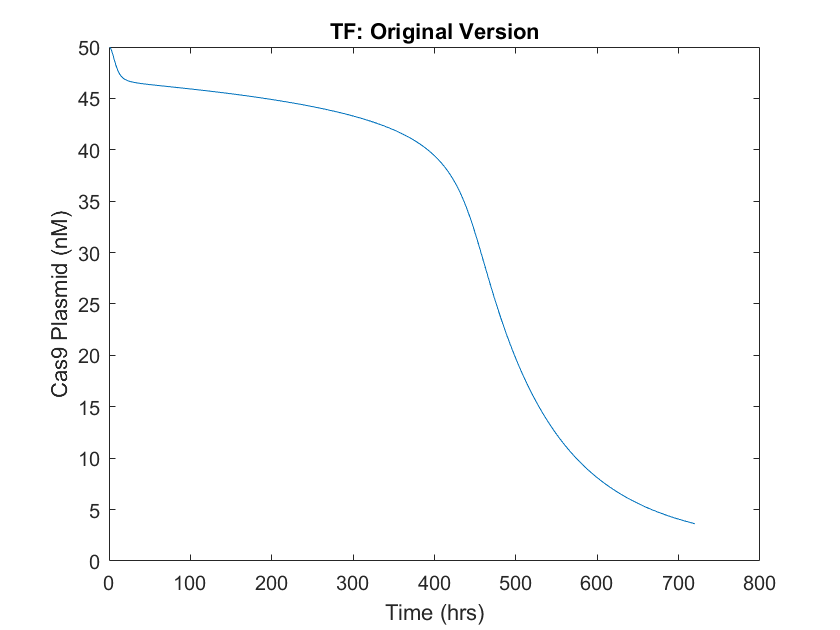

% Set tspan
tspan = [0, 720];

% Run model
[tint, yint] = GeneTherapySystemElimination(tspan, varsToUse);

% Plot
plot(tint, yint);
title('TF: Original Version')
xlabel('Time (hrs)')
ylabel('Cas9 Plasmid (nM)')

### Clean Version: No idexing of variables

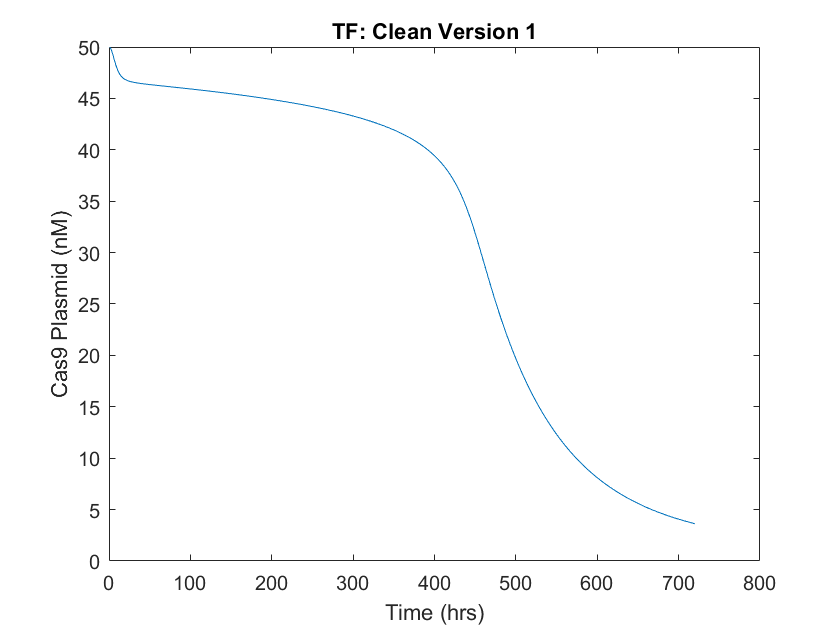

% Run model
[tint, yint] = tf(tspan, varsToUse);

% Plot
plot(tint, yint);
title('TF: Clean Version 1')
xlabel('Time (hrs)')
ylabel('Cas9 Plasmid (nM)')

## Cre

### Original Code

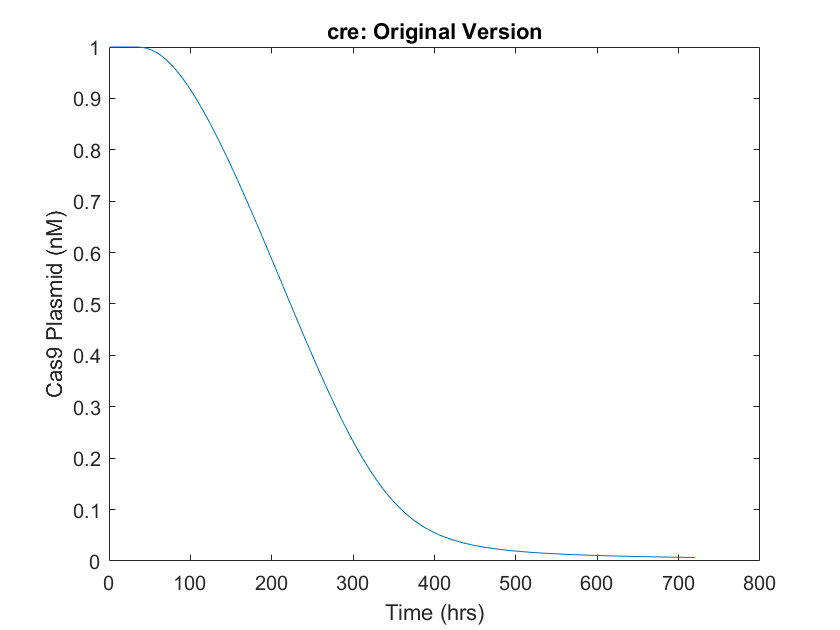

% Read in a table, get all vars
T = readtable('terms-creRecombination.csv');
fit = 'fit1';
FitTable = T(:,{'varName', [fit, '_fit'], [fit, '_std']});
vars = table2cell(FitTable);
varsToUse = zeros(1, length(vars));
for k = 1:length(vars)
    varsToUse(1, k) = vars{k, 2};
end

% Set tspan
tspan = [0, 720];

% Run model
[tint, yint] = creRecombination(tspan, varsToUse);

% Plot
plot(tint, yint);
title('cre: Original Version')
xlabel('Time (hrs)')
ylabel('Cas9 Plasmid (nM)')

### Clean Version: No indexing of variables